# Batch Chemical Reactor Design

- Chemical reactor is a vessel in which chemical reaction is carried out. 

- Batch reactor is a type of non-continuous chemical reactor. 

- In batch reactor, the reactants are fed (charged) into the reactor vessel only at the begining of reaction. 

- No output is drawn from the reactor untill the batch time has reached.

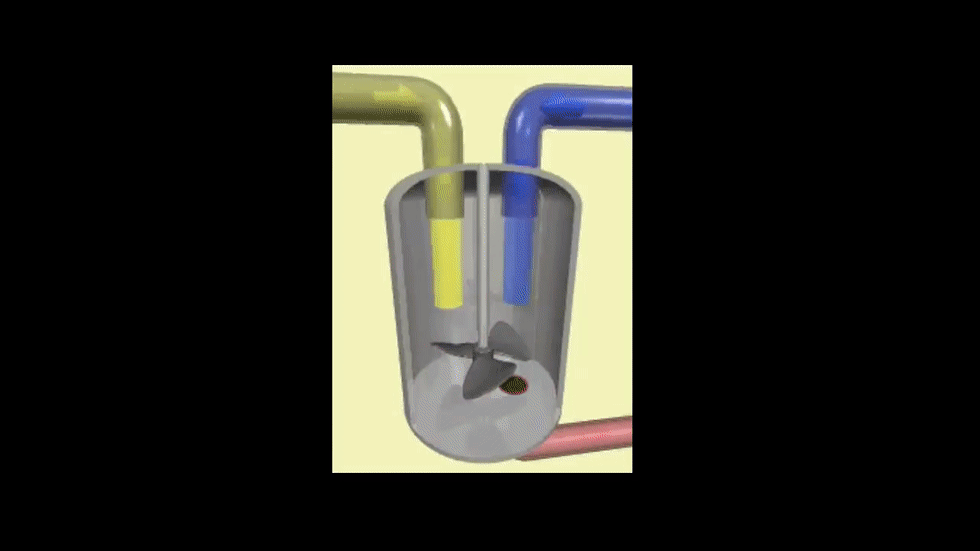

For example: -  

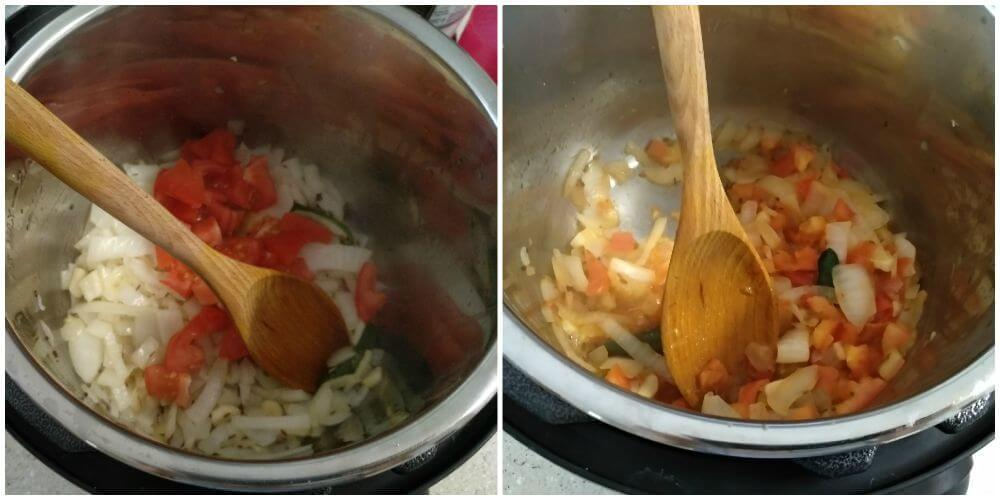. 

## Let us cook tasty food


$$\textrm{Vegtables}\;\left(\mathrm{A}\right)\to \textrm{Cooked}\;\textrm{food}\;\left(\mathrm{B}\right)\iff \textrm{burnt}\;\textrm{food}\;\left(\mathrm{C}\right)$$


### Mass balance of vegetables (A)


$$\begin{array}{l}
\textrm{Input}\;\textrm{flowrate}=\textrm{Output}\;\textrm{flowrate}+\textrm{Accumulation}\;\textrm{in}\;\textrm{Reactor}+\textrm{Dissapearance}\;\textrm{by}\;\textrm{Reaction}\\
\\
\textrm{Vegetables}\;\textrm{coming}\;\textrm{in}=\textrm{Vegetables}\;\textrm{going}\;\textrm{out}+\textrm{Vegetables}\;\textrm{left}\;\textrm{in}\;\textrm{Reactor}+\textrm{Cooked}\;\textrm{vegetables}\\
\\
\;\Rightarrow \;\;0\;=\;0+\frac{{\textrm{dN}}_{\mathrm{A}} }{\textrm{dt}}+\mathrm{V}\left(-{\mathrm{r}}_{\mathrm{A}} \right)\\
\;\\
\Rightarrow \;\;\;\mathrm{t}=-\int_{{\mathrm{N}}_{\mathrm{A},\mathrm{o}} }^{{\mathrm{N}}_{\mathrm{A}} } \frac{1}{\mathrm{V}}\frac{{\textrm{dN}}_{\mathrm{A}} }{\left(-{\mathrm{r}}_{\mathrm{A}} \right)}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\\
\Rightarrow \;\;\;\mathrm{t}=\int_0^{\chi_{\mathrm{A}} } \frac{1}{\mathrm{V}}\frac{{\mathrm{d}\chi }_{\mathrm{A}} }{\left(-{\mathrm{r}}_{\chi_{\mathrm{A}} } \right)}\;\;\\
\;\\
\textrm{Here},\\
\;\\
{\mathrm{N}}_{\mathrm{A}} =\textrm{moles}\;\textrm{of}\;\mathrm{A},\;\textrm{gmol}\\
{\mathrm{N}}_{\mathrm{A},\mathrm{o}} =\textrm{moles}\;\textrm{of}\;\mathrm{A}\;\textrm{initially}\;\textrm{fed}\;\textrm{to}\;\textrm{reactor},\;\textrm{gmol}\\
-{\mathrm{r}}_{\mathrm{A}} =\textrm{rate}\;\textrm{of}\;\textrm{dissapearance}\;\textrm{of}\;\mathrm{A},\frac{\textrm{mol}}{\textrm{Ls}}\\
\mathrm{t}=\textrm{time},\mathrm{s}\\
\mathrm{V}=\textrm{Volume}\;\textrm{of}\;\textrm{the}\;\textrm{reactor},\mathrm{L}\\
\chi_{\mathrm{A}} =\frac{{{\mathrm{N}}_{\mathrm{A},\mathrm{o}} -\mathrm{N}}_{\mathrm{A}} }{{\mathrm{N}}_{\mathrm{A},\mathrm{o}} }=\textrm{conversion}\;\textrm{of}\;\mathrm{A}
\end{array}$$


#### Rates of reactions


$$\begin{array}{l}
{\mathrm{r}}_{\mathrm{A}} =-\frac{\textrm{dA}}{\textrm{dt}}{\;\;=\;\mathrm{k}}_1 \mathrm{A}\\
{\mathrm{r}}_{\mathrm{B}} =\;-\frac{\textrm{dB}}{\textrm{dt}}\;={\mathrm{k}}_2 \mathrm{B}-{\mathrm{k}}_1 \mathrm{A}-{\mathrm{k}}_4 \mathrm{C}\\
{\mathrm{r}}_{\mathrm{C}} =\;-\frac{\textrm{dC}}{\textrm{dt}}\;={\mathrm{k}}_4 \mathrm{C}-{\mathrm{k}}_3 \mathrm{B}
\end{array}$$


## How to solve the model equations? 

clear all

#### Step 1: Declare symbols for each variable in model equation

syms t A(t) B(t) C(t) k1 k2 k3 k4

#### Step 2: Declare rate equations

rA = -diff(A,1) == k1*A; % mol_A/m^3-s
rB = -diff(B,1) == k2*B - k1*A - k4*C; % mol_B/m^3-s
rC = -diff(C,1) == k4*C - k3*B; % mol_C/m^3-s

#### Step 3: Substitute rate constants

rA = subs(rA, k1, 1e-2);
rB = subs(rB, {k1, k2, k3, k4}, {1e-2, 5e-3, 3e-3, 1e-3});
rC = subs(rC, {k3, k4}, {3e-3, 1e-3});

Alrenatively*:  [rA, rB, rC] = deal({subs({rA, rB, rC},{k1,k2,k3,k4},{1e-2,5e-3,3e-3,1e-3})});

#### Step 4: Solve the equations

sol = dsolve([rA;rB;rC],[A(0)==100; B(0)==0; C(0)==0]);

Split the solution for different species 

[A(t), B(t), C(t)] = deal(sol.A, sol.B, sol.C); % mol

#### STEP 5: Plot the solution

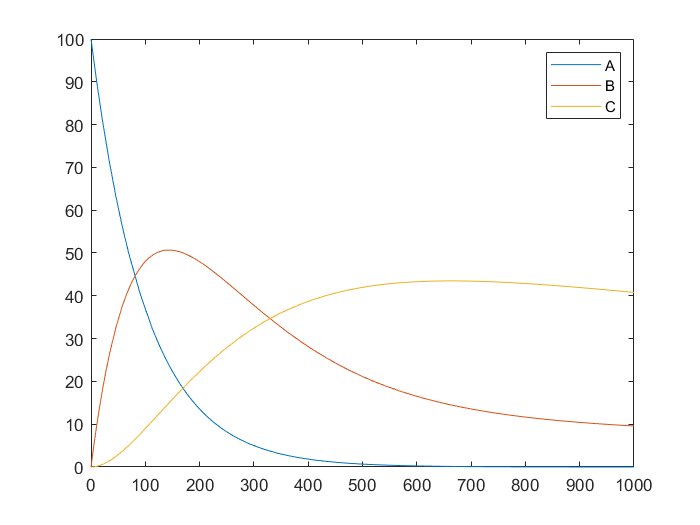

fplot([A,B,C],[0,1000]);
legend A B C

#### Find operating time required for maximum amount of cooked food (B)/ burnt food (C)

operatingTime = sym(0:1000); % s
ConcProf_A = double(A(operatingTime));% mol_A
ConcProf_B = double(B(operatingTime));% mol_B
ConcProf_C = double(C(operatingTime));% mol_C



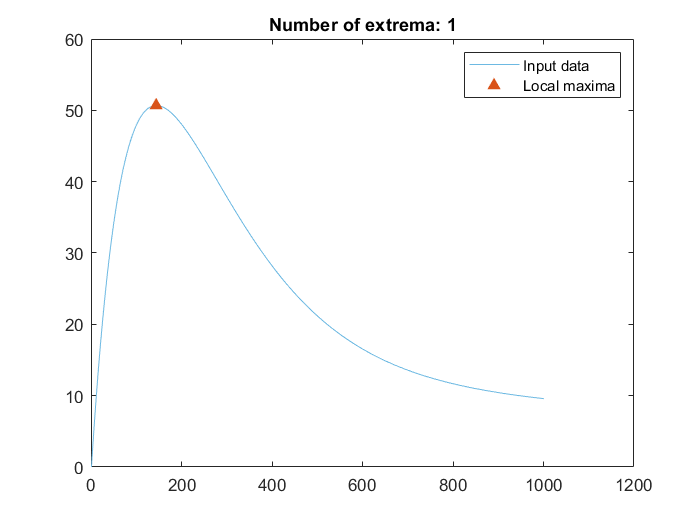

% Find local maxima
maxIndices2 = islocalmax(ConcProf_B);

% Visualize results
clf
plot(ConcProf_B,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(maxIndices2),ConcProf_B(maxIndices2),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices2))])
hold off
legend